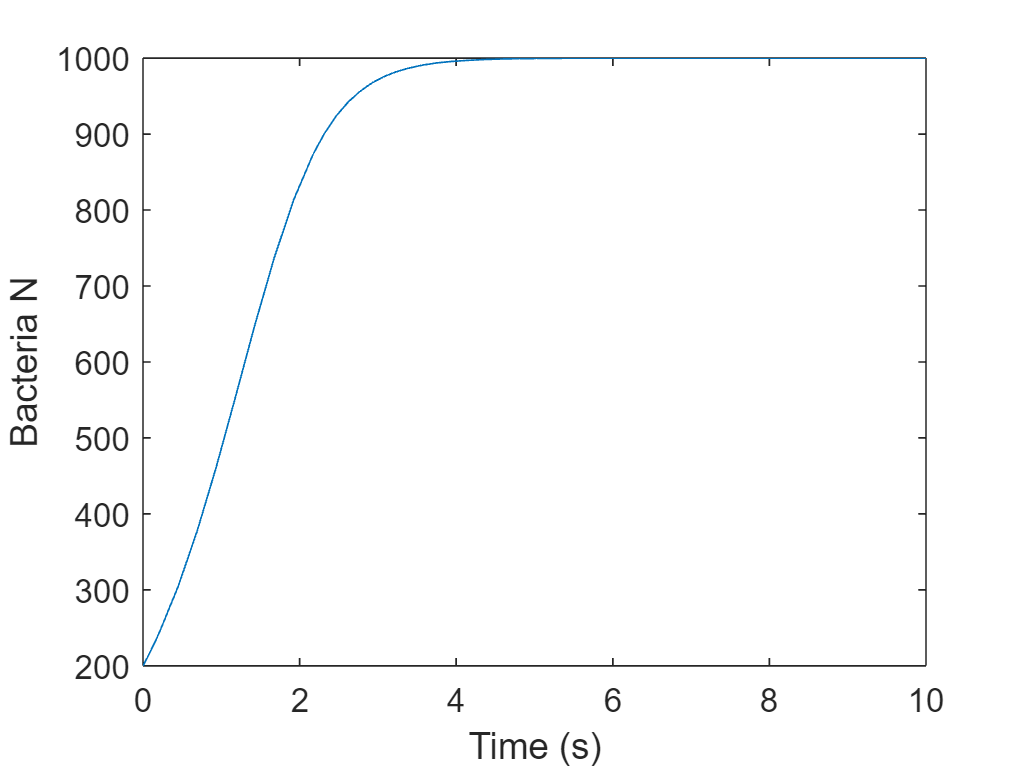

lambda = 1;
theta = 10^3;
alpha=2;

f = @(n) lambda*n*(1-(n/theta)^alpha);

dndt = @(t,x)[f(x)];

[T,X] = ode45(dndt, [0,10], 200);

figure
plot(T,X)
ylabel('Bacteria N')
xlabel('Time (s)')

time = [0,30,59,89,118,148,183]

time =      0    30    59    89   118   148   183


raw_data = [0.09,0.12,0.20,0.38,0.58,0.76,1.10]

raw_data =     0.0900    0.1200    0.2000    0.3800    0.5800    0.7600    1.1000


bacteria_lb = reshape(raw_data,[7,1])

bacteria_lb =     0.0900
    0.1200
    0.2000
    0.3800
    0.5800
    0.7600
    1.1000


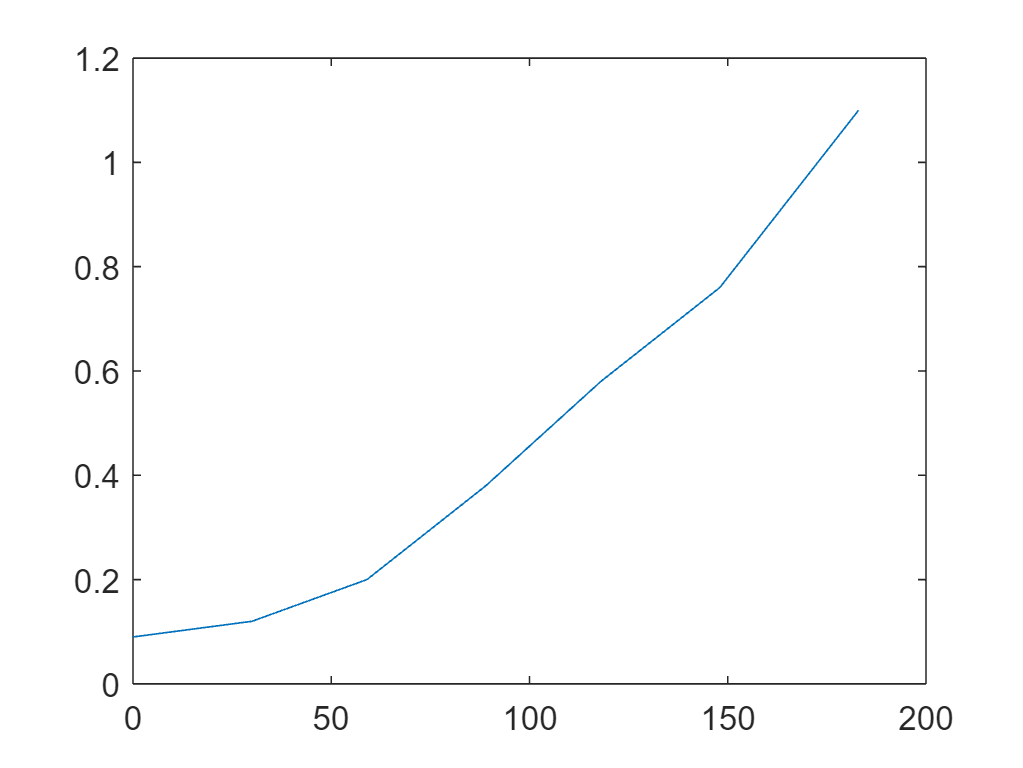

plot(time, bacteria_lb)

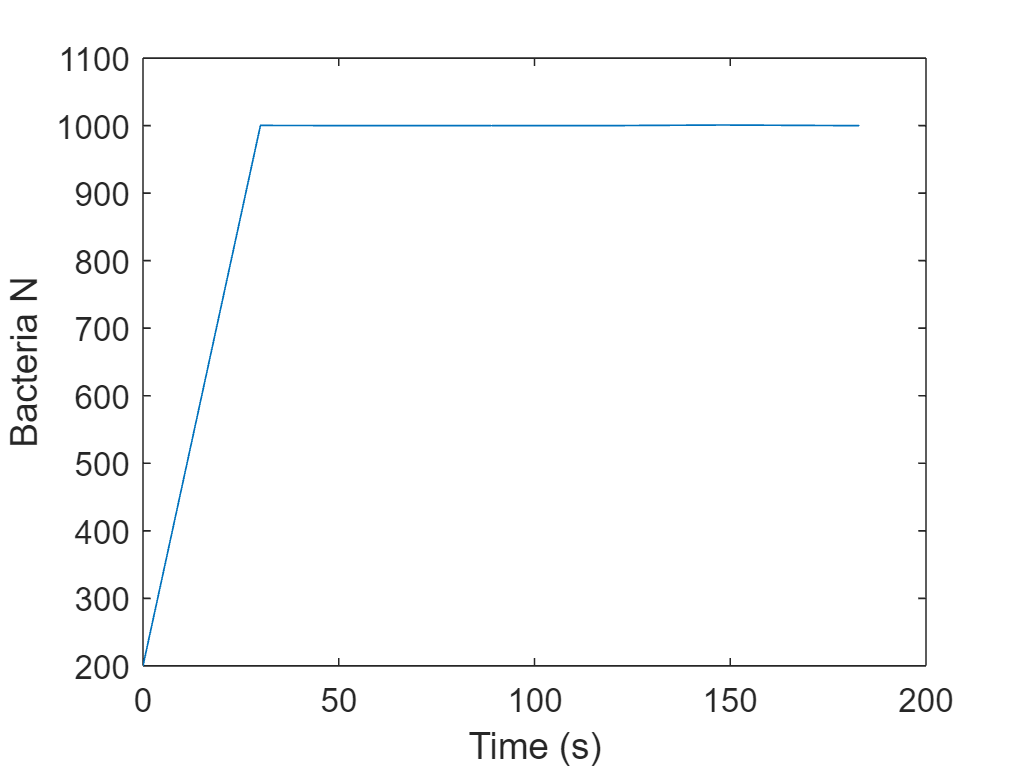

%simulated value at each step, starts at 200, not 0
f2 = @(n) lambda*n*(1-(n/theta)^alpha);

dndt = @(t,x)[f(x)];

[T,X_sim] = ode45(dndt, time, 200); %set times

figure
plot(T,X_sim)
ylabel('Bacteria N')
xlabel('Time (s)')

%sum of squares
squares = sum((X_sim - bacteria_lb).^2)

squares = 6.0356e+06


my_guess = [1, 0.01, 0.01, 1];
my_answer = fminsearch(@finderror, my_guess)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.022236 



my_answer =    -0.0483    0.0011    0.0357    0.1460


min_error = finderror(my_answer);


finderror(my_answer)

ans = 0.0222

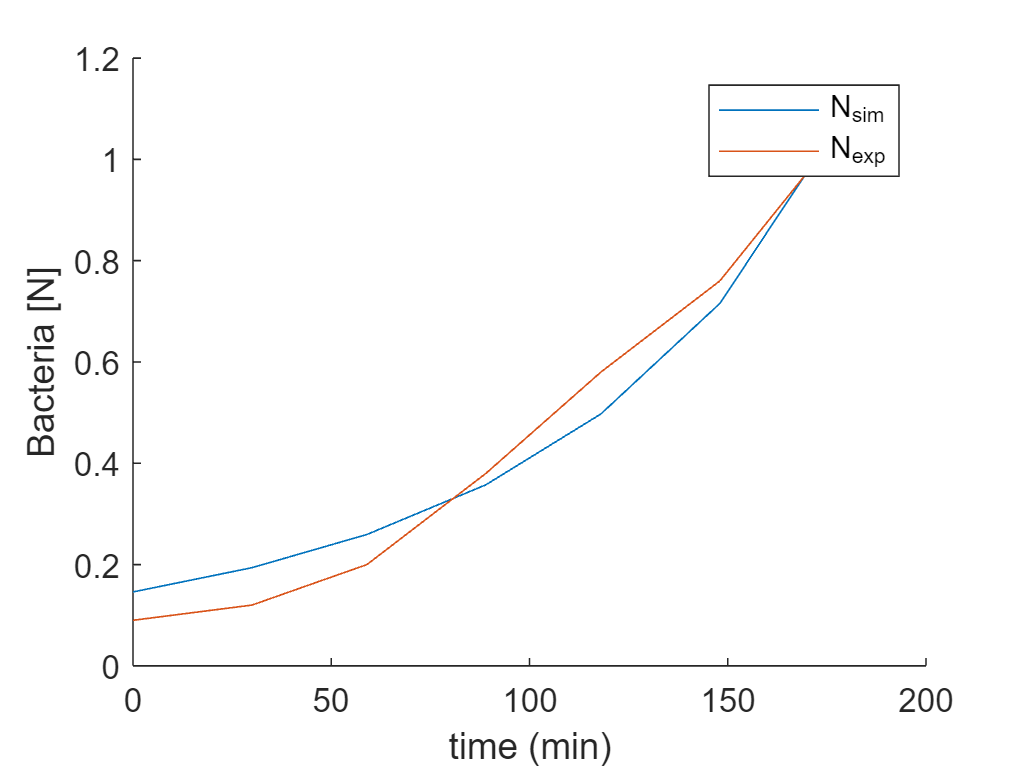

lambda = my_answer(1);
theta = my_answer(2);
alpha = my_answer(3);
my_time = [0,30,59,89,118,148,183];
initial_od = my_answer(4);

f = @(n) lambda*n*(1-(n/theta)^alpha);

dxdt = @(t,x)[f(x)];

[T,x_sim] = ode45(dxdt, my_time, initial_od);

raw_data = [0.09,0.12,0.20,0.38,0.58,0.76,1.10];
bacteria = reshape(raw_data,size(x_sim));

figure; hold on
plot(my_time,x_sim);
plot(my_time,bacteria);
xlabel('time (min)')
ylabel('Bacteria [N]')
legend('N_{sim}', 'N_{exp}')